# stability analysis across sep and exp 

#### 0 pre-processing 

load('dTT_SYN_6pair_sep_exp_ROI.mat')
N=length(Ee);
dis_th=40;
[Ee,~]=remove_contamination(Ee,dis_th);

ans = 'Pair1,Mouse1,53(25%) cells removed'

ans = 'Pair1,Mouse2,59(25%) cells removed'

ans = 'Pair2,Mouse1,84(48%) cells removed'

ans = 'Pair2,Mouse2,51(22%) cells removed'

ans = 'Pair3,Mouse1,83(34%) cells removed'

ans = 'Pair3,Mouse2,89(38%) cells removed'

ans = 'Pair4,Mouse1,57(33%) cells removed'

ans = 'Pair4,Mouse2,87(32%) cells removed'

ans = 'Pair5,Mouse1,64(27%) cells removed'

ans = 'Pair5,Mouse2,84(30%) cells removed'

ans = 'Pair6,Mouse1,69(25%) cells removed'

ans = 'Pair6,Mouse2,72(27%) cells removed'

[Es,~]=remove_contamination(Es,dis_th);

ans = 'Pair1,Mouse1,35(18%) cells removed'

ans = 'Pair1,Mouse2,34(16%) cells removed'

ans = 'Pair2,Mouse1,50(25%) cells removed'

ans = 'Pair2,Mouse2,29(13%) cells removed'

ans = 'Pair3,Mouse1,42(19%) cells removed'

ans = 'Pair3,Mouse2,47(23%) cells removed'

ans = 'Pair4,Mouse1,61(37%) cells removed'

ans = 'Pair4,Mouse2,40(17%) cells removed'

ans = 'Pair5,Mouse1,38(19%) cells removed'

ans = 'Pair5,Mouse2,35(15%) cells removed'

ans = 'Pair6,Mouse1,39(16%) cells removed'

ans = 'Pair6,Mouse2,36(16%) cells removed'

#### 1 Power stability of population rate 

1.1 The mean power in 7 specified frequency ranges over first and second halves of the experiment. Signals of 80 neurons in 14 minutes were taken from each animal. 

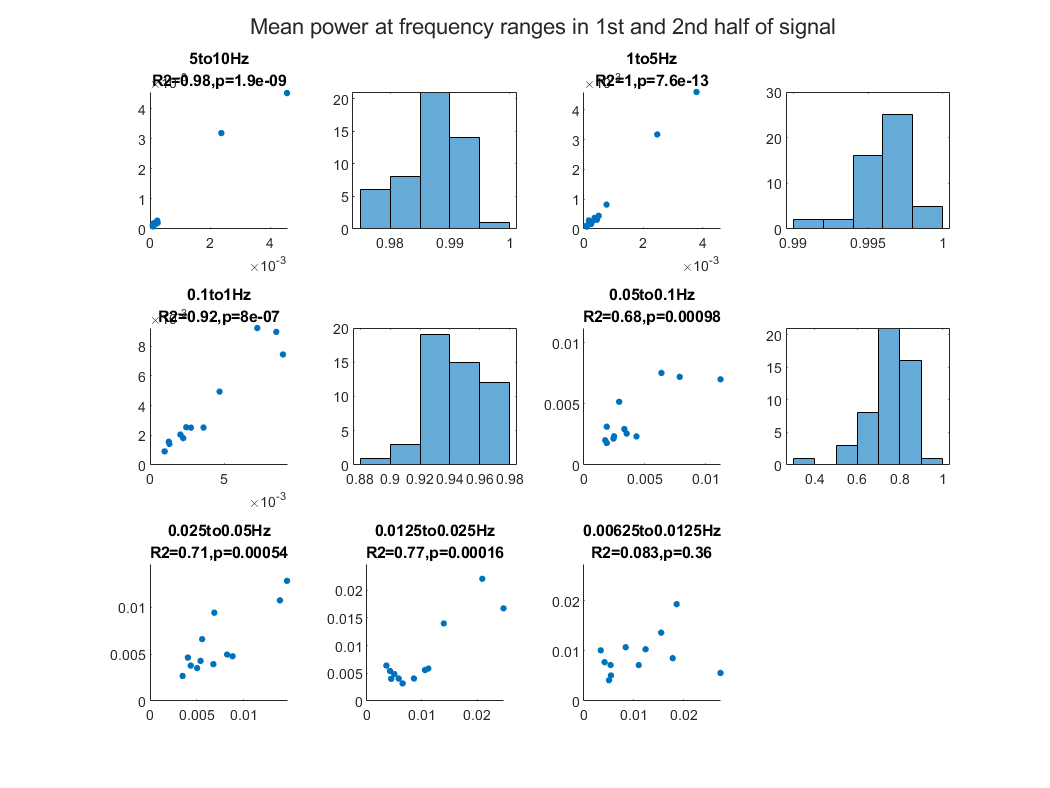

W = {[5 10] [1 5] [0.1 1] [0.05 0.1] [0.025 0.05] [0.0125 0.025] [0.00625 0.0125]};
ncell=80;nsecond=60*14;
bpca=[];
for n=1:50 % 50 draws of cells 
    k=0;
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Ee{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        for f=1:length(W)
            ca=mean(zscore(Ee{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
            ca1 = ca(1:round(end/2)); % divide signal into two halves
            ca2 = ca(1+round(end/2):end);
            bpca(n,k,f,1)=bandpower(ca1,30,W{f});% mean power in specified ranges
            bpca(n,k,f,2)=bandpower(ca2,30,W{f});
        end
    end
end
end
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
t=tiledlayout(3,4,'TileSpacing',"compact");
for f=1:length(W)
    nexttile
    x=mean(bpca(:,:,f,1));y=mean(bpca(:,:,f,2));
    scatter(x,y,15,'filled')
    xlim([0 max([x,y])]);ylim([0 max([x,y])])
    axis square 
    [r,p]=corr(x',y');r2=r.^2;
    title(sprintf('%gto%gHz\nR2=%.2g,p=%.2g',W{f}(1),W{f}(2),r2,p))
    if any(f==[1 2 3 4])
        nexttile
        h=corr(bpca(:,:,f,1)',bpca(:,:,f,2)');
        h=h(1:size(h,1)+1:end);
        histogram(h);
    end
end
title(t,'Mean power at frequency ranges in 1st and 2nd half of signal')

1.2 The mean power in 7 specified frequency ranges over first and second halves of the separation. Signals of 80 neurons in 10 minutes were taken from each animal. 

W = {[5 10] [1 5] [0.1 1] [0.05 0.1] [0.025 0.05] [0.0125 0.025] [0.00625 0.0125]};
ncell=80;nsecond=60*10;
bpca=[];
for n=1:50 % 50 draws of cells 
    k=0;
for p=1:length(Es)
    for m=1:2
        [nf,nc]=size(Es{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        for f=1:length(W)
            ca=mean(zscore(Es{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
            ca1 = ca(1:round(end/2)); % divide into two halves
            ca2 = ca(1+round(end/2):end);
            bpca(n,k,f,1)=bandpower(ca1,30,W{f});% mean power in specified ranges
            bpca(n,k,f,2)=bandpower(ca2,30,W{f});
        end
    end
end
end

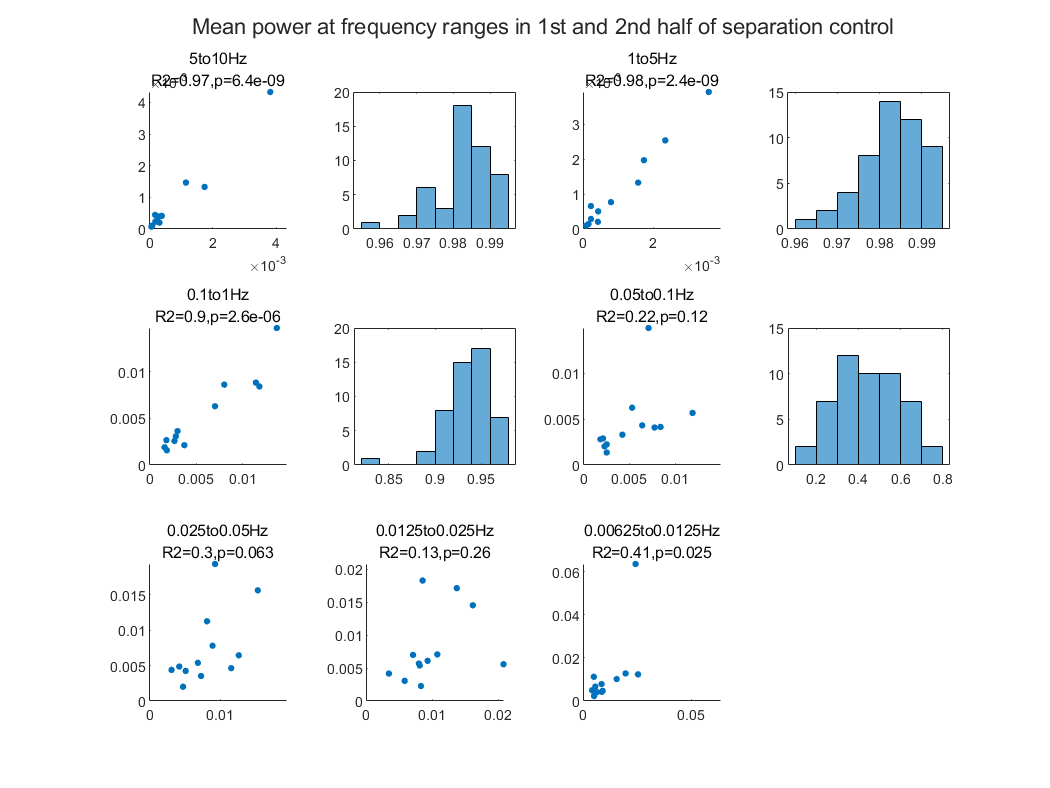

f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
t=tiledlayout(3,4,'TileSpacing',"compact");
for f=1:length(W)
    nexttile
    x=mean(bpca(:,:,f,1));y=mean(bpca(:,:,f,2));
    scatter(x,y,15,'filled')
    xlim([0 max([x,y])]);ylim([0 max([x,y])])
    axis square 
    [r,p]=corr(x',y');r2=r.^2;
    title(sprintf('%gto%gHz\nR2=%.2g,p=%.2g',W{f}(1),W{f}(2),r2,p),'FontWeight','normal','FontSize',8)
    if any(f==[1 2 3 4])
        nexttile
        h=corr(bpca(:,:,f,1)',bpca(:,:,f,2)');
        h=h(1:size(h,1)+1:end);
        histogram(h);
    end
end
title(t,'Mean power at frequency ranges in 1st and 2nd half of separation control')

1.3 The mean power in 7 specified frequency ranges over separation and experiment. Signals of 80 neurons in 7 minutes (sep and exp respectively) were taken from each animal. 

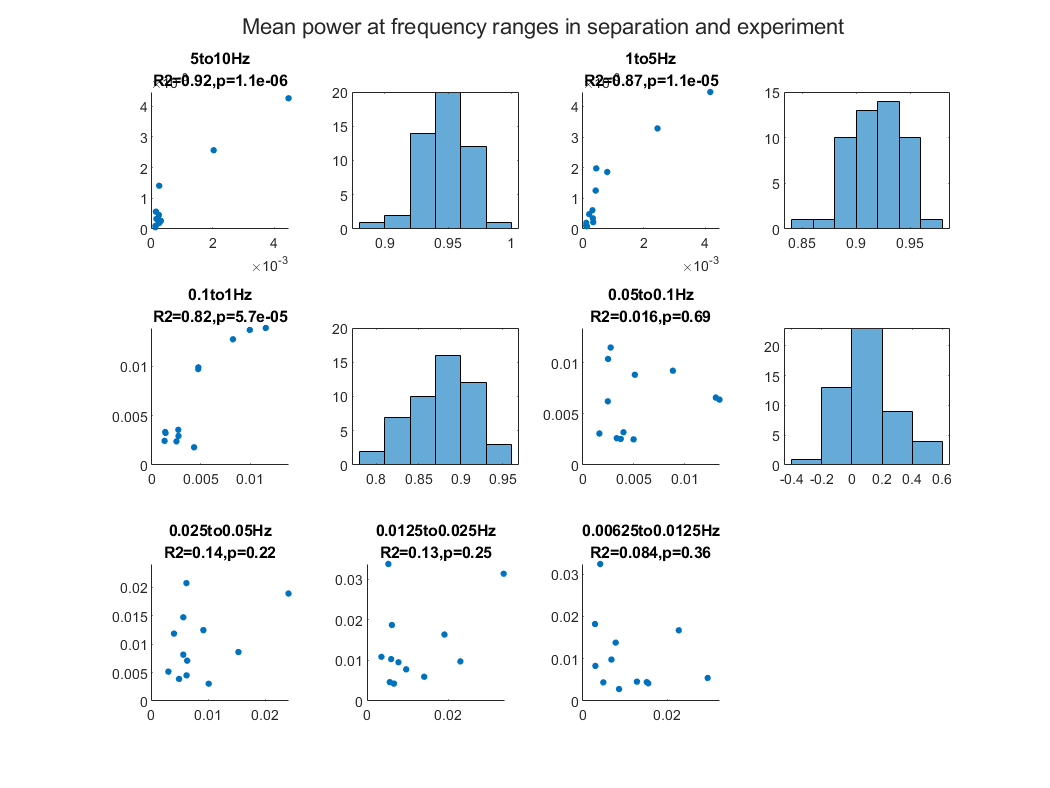

W = {[5 10] [1 5] [0.1 1] [0.05 0.1] [0.025 0.05] [0.0125 0.025] [0.00625 0.0125]};
close all 
ncell=80;nsecond=60*7;bpca=[];
for n=1:50
k=0;
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Es{p}{m}.dFFCalciumTraces);
        [~,nce]=size(Ee{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);rpe=randperm(nce);
        takecell=rp(1:ncell);takecelle=rpe(1:ncell);
        for f=1:length(W)
            ca1=mean(zscore(Ee{p}{m}.dFFCalciumTraces(1:30*nsecond/2,takecelle)),2); % mean of random cells in 7 minutes
            ca2=mean(zscore(Es{p}{m}.dFFCalciumTraces(1:30*nsecond/2,takecell)),2);
            bpca(n,k,f,1)=bandpower(ca1,30,W{f});% mean power in specified ranges
            bpca(n,k,f,2)=bandpower(ca2,30,W{f});
        end
    end
end
end
f2=figure;f2.Position(3)=1.5*f2.Position(3);f2.Position(4)=1.5*f2.Position(4);
t=tiledlayout(3,4,'TileSpacing',"compact");
for f=1:length(W)
    nexttile
    x=mean(bpca(:,:,f,1));y=mean(bpca(:,:,f,2));
    scatter(x,y,15,'filled')
    xlim([0 max([x,y])]);ylim([0 max([x,y])])
    axis square 
    [r,p]=corr(x',y');r2=r.^2;
    title(sprintf('%gto%gHz\nR2=%.2g,p=%.2g',W{f}(1),W{f}(2),r2,p))
    if any(f==[1 2 3 4])
        nexttile
        h=corr(bpca(:,:,f,1)',bpca(:,:,f,2)');
        h=h(1:size(h,1)+1:end);
        histogram(h);
    end
end
title(t,'Mean power at frequency ranges in separation and experiment')

1.3 compare experiment and separation power 

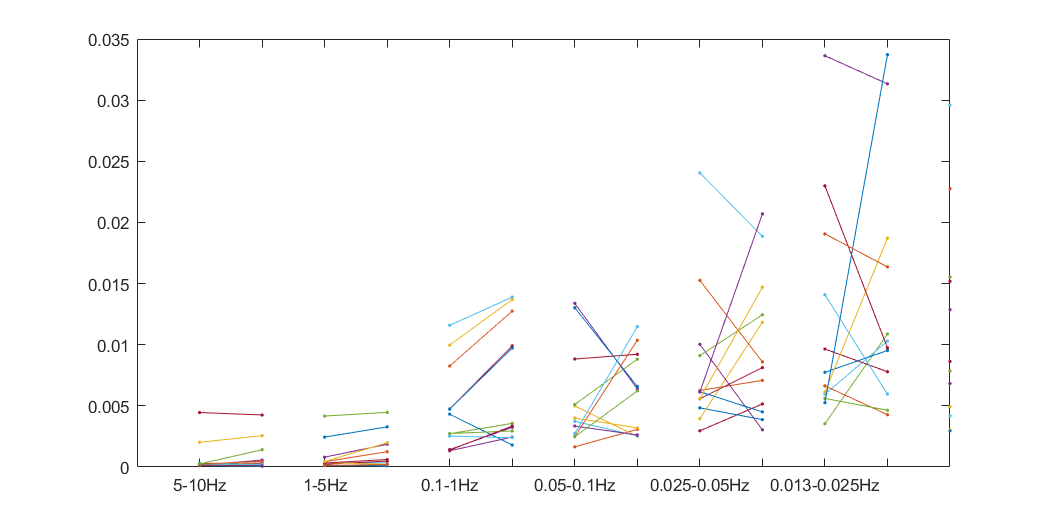

tlabel=strings(1,2*length(Ee));
f=figure;f.Position(3)=1.5*f.Position(3);
for f=1:length(W)
    % plot(repmat([2*f-1,2*f],2*length(Ee),1),squeeze(bpca(:,:,f))');
    plot([2*f-1,2*f],squeeze(mean(bpca(:,:,f,:))),'.-');xlim([0 13])
    hold on
    tlabel(2*f-1)=sprintf('%.2g-%.2gHz',W{f}(1),W{f}(2));
end
xticks(1:12);xticklabels(tlabel);

% for each frequency, first dot experiment, second dot separation

#### Power spectrum 

Power spectrum of the mean of 80 neurons from each animal between frequency 0.01-10Hz and 10 minutes. 

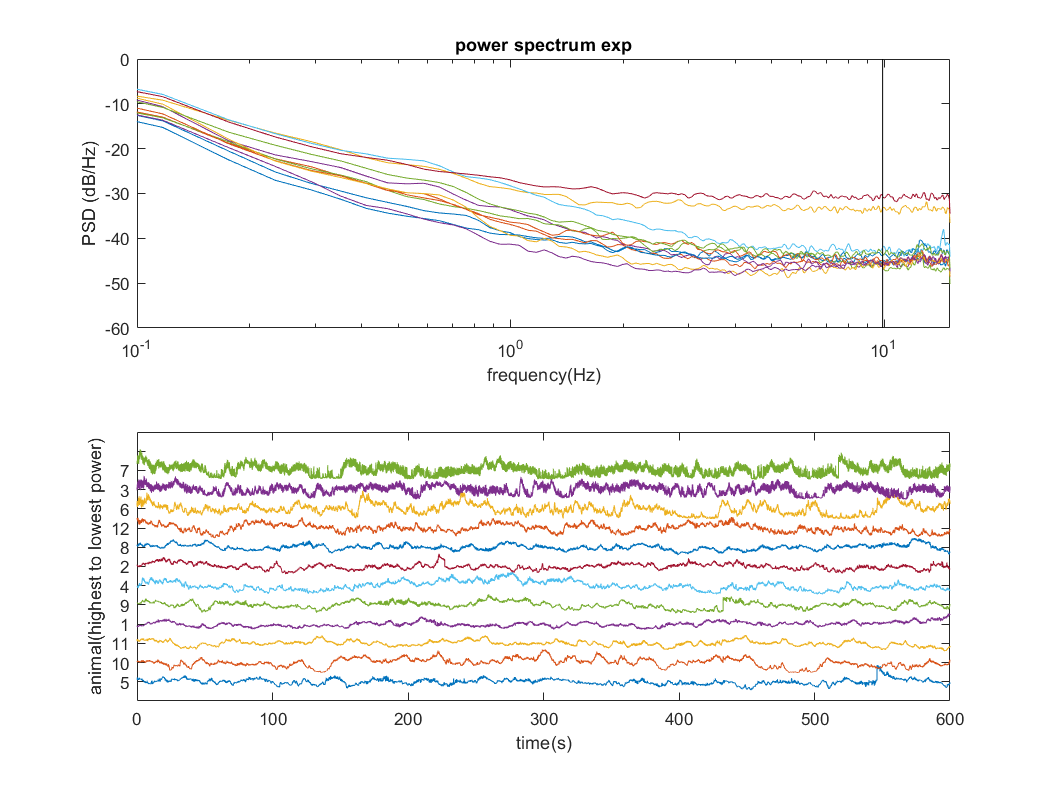

close all
ncell=80;nsecond=60*10;
k=0;
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Ee{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        ca(k,:)=mean(zscore(Ee{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
        [pxx(k,:),fre]=pwelch(ca(k,:),30*10,[],[],30);
        subplot(2,1,1)
        plot(fre,10*log10(pxx(k,:)))
        hold on 
    end
end
xlim([0.1 15]);set(gca,'xscale','log');xlabel('frequency(Hz)');ylabel('PSD (dB/Hz)')
line([fre(170),fre(170)],ylim,'color','k');
hold off
title('power spectrum exp')
[~,ind]=sort(pxx(:,170));% sort at ~ frequency 10Hz
subplot(2,1,2)
plot(1/30:1/30:600,ca(ind,:)'+repelem(1:12,length(ca),1));xlabel('time(s)');ylabel('animal(highest to lowest power)');
yticks(1:13);yticklabels(ind)

separation control 

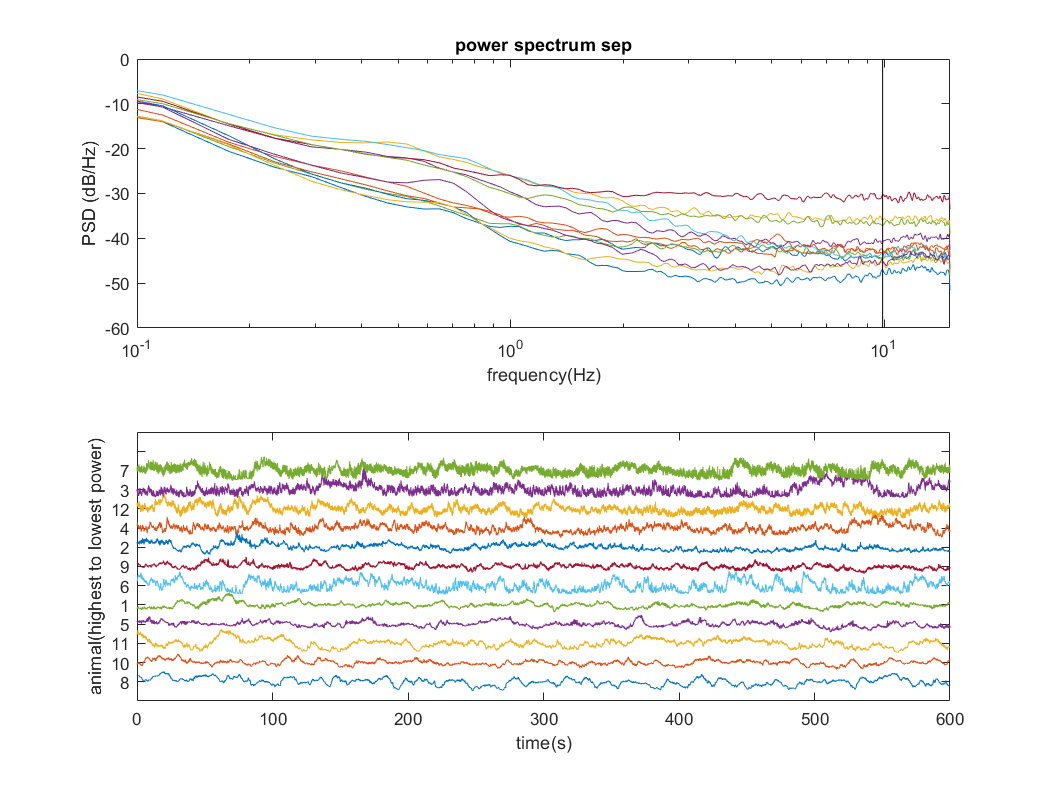

close all
ncell=80;nsecond=60*10;
k=0;
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Es{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        ca(k,:)=mean(zscore(Es{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
        [pxx(k,:),fre]=pwelch(ca(k,:),30*10,[],[],30);
        subplot(2,1,1)
        plot(fre,10*log10(pxx(k,:)))
        hold on 
    end
end
xlim([0.1 15]);set(gca,'xscale','log');xlabel('frequency(Hz)');ylabel('PSD (dB/Hz)')
line([fre(170),fre(170)],ylim,'color','k');
hold off
title('power spectrum sep')
[~,ind]=sort(pxx(:,170));% sort at ~ frequency 10Hz
subplot(2,1,2)
plot(1/30:1/30:600,ca(ind,:)'+repelem(1:12,length(ca),1));xlabel('time(s)');ylabel('animal(highest to lowest power)');
yticks(1:13);yticklabels(ind)